# Part II: Introduction to Battery Modelling with BattMo

**Dr. Sridevi Krishnamurthi **and** Dr. Simon Clark, ***SINTEF AS, Battery Technology, Trondheim, Norway*

In part 1 of the modeling guide, we provided an overview of battery modeling, introduced key terms, and explained how to use BattMo. In part 2, we will delve into the DFN model in detail, examine its parameters, explore how varying these parameters affects the model, and assess their impact on the cell's voltage discharge profile and overall capacity.

## 1. DFN Model overview

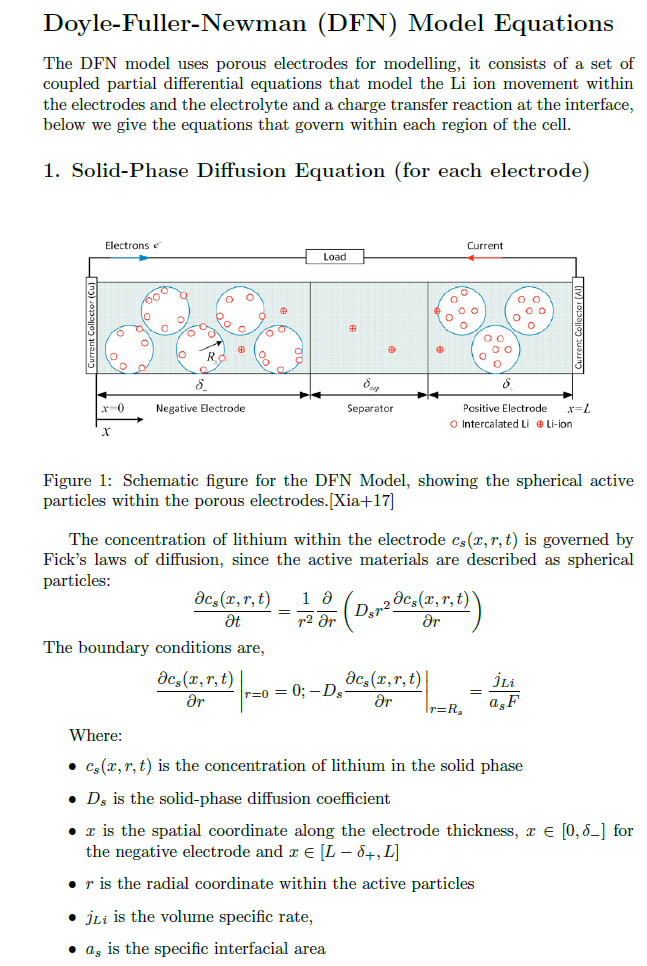

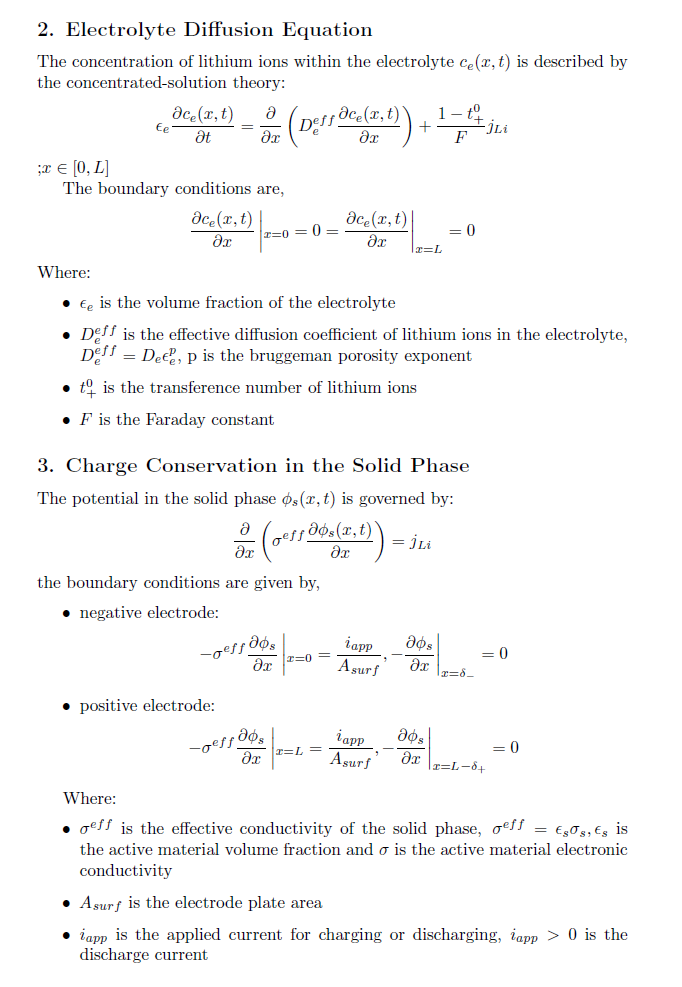

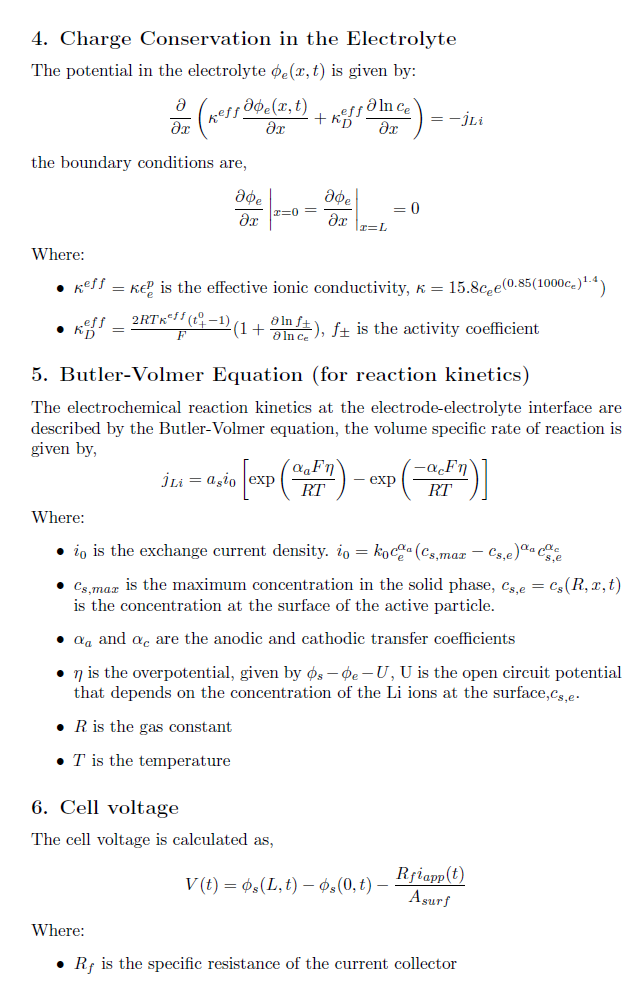

Electrochemical system: Thermodynamics, Kinetics,Transport

DFN model parts:

Model equations for transport in porous electrode -Fick's law, electron transport-ohm's law, charge transport at interface:butler volmer eqn, mass transport in electrolyte:concentrated solution theory.

Overpotential figure:

vary the parameters for thermodynamics at slow C rate c/20: maximum Li ion concentration,active materials

vary the transport parameters at high c rate: Diffusion coeffiecient,particle radius of electrode materials

vary the kinetic parameters-rate constant,exchange current density,activation energy,charge transfer coefficients

check_json=parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
disp(check_json.PositiveElectrode.Coating.ActiveMaterial.massFraction);

    0.9500



## **Example 1. C rate **

crate_array=[linspace(0.1,3,6)];
crate="Control.CRate";
plot_capacities(crate_array,crate)

Solving timestep 01/45:          -> 30 Seconds, 937 Milliseconds
Solving timestep 02/45: 30 Seconds, 937 Milliseconds -> 61 Seconds, 875 Milliseconds
Solving timestep 03/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 04/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 05/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 06/45: 495 Seconds -> 990 Seconds
Solving timestep 07/45: 990 Seconds -> 1980 Seconds
Solving timestep 08/45: 1980 Seconds -> 2970 Seconds
Solving timestep 09/45: 2970 Seconds -> 1 Hour, 360 Seconds
Solving timestep 10/45: 1 Hour, 360 Seconds -> 1 Hour, 1350 Seconds
Solving timestep 11/45: 1 Hour, 1350 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 12/45: 1 Hour, 2340 Seconds -> 1 Hour, 3330 Seconds
Solving timestep 13/45: 1 Hour, 3330 Seconds -> 2 Hours, 720 Seconds
Solving timestep 14/45: 2 Hours, 720 Seconds -> 2 Hours, 1710 Seconds
Solving timestep 15/45: 2 Hours, 1710 Seconds -

 As discussed earlier, the DFN model incorporates various parameters. In the following sections, we will explore how adjusting some of these parameters influences the capacities. 

### 2. Thermodynamic parameters

#### **Example 2. **volume fraction of active material and binder in electrode

electrode_mf="PositiveElectrode.";
Crate_mf=0.1;
ele_mf=[linspace(0.90,0.96,4)];
negative_binder_mf=0.97-ele_mf;
positive_binder_mf=0.975-ele_mf;
markers={'-',"o","x","+",};
output = cell(size(ele_mf));
therm_parameter_1=strcat(electrode_mf,"Coating.ActiveMaterial.massFraction");
therm_parameter_2=strcat(electrode_mf,"Coating.Binder.massFraction");
jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct_default});

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.
parameter SOC is assigned twice with different values. we use the value from first jsonstruct.


% instantiate an empty figure
figure()
% use a for-loop to iterate through the vector of volume fraction of active materials
for i = 1:numel(ele_mf)
        jsonstruct_modified.Control.CRate=Crate_mf;
        c1 = split(therm_parameter_1,'.');
        c2=  split(therm_parameter_2,'.');
        jsonstruct_modified = setfield(jsonstruct_modified,c1{:},ele_mf(i)); % active material massfraction
        if strcmp(c1{1}, 'PositiveElectrode')
            jsonstruct_modified = setfield(jsonstruct_modified,c2{:},positive_binder_mf(i));% binder massfraction
        else
            jsonstruct_modified = setfield(jsonstruct_modified,c2{:},negative_binder_mf(i)); % binder massfraction
        end
        jsonstruct_modified.TimeStepping.totalTime = (1./jsonstruct_modified.Control.CRate) .* 3600 .* 1.2;
        % Run the simulation and store the results in the output cell array
        output{i} = runBatteryJson(jsonstruct_modified);        
        % Retrieve the states from the simulation result
        states = output{i}.states;
        % Extract time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % Calculate the capacity
        capacity = time .* current;
        if any(capacity>0)
        start_index_current_pos=find(current >= 0, 1);
        time_discharge=time(start_index_current_pos);
        discharge_capacity = (time-time_discharge) .* current;
        start_index = find(discharge_capacity == 0, 1);
        end_index = find(discharge_capacity > 0, 1,"last");
        plot(discharge_capacity(start_index:end_index)/(hour*milli),voltage(start_index:end_index), markers{i}, 'linewidth', 3)
        else
            plot(capacity/(hour*milli),voltage) 
        end
        L{i} = strcat(num2str(ele_mf(i)));
        legend(L);
    hold on
end

Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

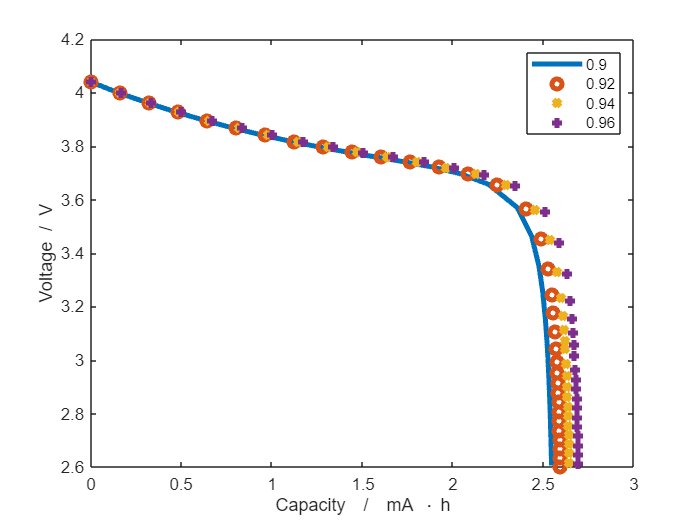

hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')

### 3. Kinetic parameters

#### **Example 3. **Activation energy of reaction at the surface of the active particles

electrode_Ea="PositiveElectrode.";
crate_Ea=3;
kinetic_parameter_4=strcat(electrode_Ea,"Coating.ActiveMaterial.Interface.activationEnergyOfReaction");% does not seem to affect the discharge profile
kinetic_parameter_4_vals=[linspace(2000,7000,5),5000];
plot_capacities(kinetic_parameter_4_vals,kinetic_parameter_4,crate_Ea)

#### **Example 4. **Charge transfer coefficient at the surface of the active particles -Butler Volmer equation

electrode_alpha="PositiveElectrode.";
crate_alpha=3;
kinetic_parameter_2_vals=[linspace(0.1,0.9,5),0.5];
kinetic_parameter_2=strcat(electrode_alpha,"Coating.ActiveMaterial.Interface.chargeTransferCoefficient");
plot_capacities(kinetic_parameter_2_vals,kinetic_parameter_2,crate_alpha), %crate to be set to 3

#### **Example 5. **Reaction rate constant at the surface of the active particles - Butler Volmer equation exchange current density 

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

Solver failure after 9 iterations for timestep of length 5 Seconds, 531 Milliseconds. Cutting timestep.
Failure reason: Linear solver produced non-finite values.
Cutting timestep.


Solver failure after 9 iterations for timestep of length 3 Seconds, 142 Milliseconds. Cutting timestep.
Failure reason: Linear solver produced non-finite values.
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 2 Seconds, 134 Milliseconds. Cutting timestep.


Solver failure after 3 iterations for timestep of length 2 Seconds, 2 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 1 Second, 251 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 782 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 4 Seconds, 175 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

Solver did not converge in 10 iterations for timestep of length 3 Seconds, 146 Milliseconds. Cutting timestep.


Solver failure after 4 iterations for timestep of length 2 Seconds, 498 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 1 Second, 388 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 867 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 542 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 4 Seconds, 28 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 3

Solver failure after 2 iterations for timestep of length 2 Seconds, 92 Milliseconds. Cutting timestep.
Failure reason: Linear solver produced non-finite values.
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 1 Second, 307 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 817 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 3 Seconds, 632 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

Solver failure after 9 iterations for timestep of length 9 Seconds, 83 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 8 iterations for timestep of length 3 Seconds, 443 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 2 Seconds, 62 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 1 Second, 31 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 736 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 3 Seconds, 255 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 3 Seconds, 65 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 3

*** Simulation complete. Solved 45 control steps in 2 Seconds, 776 Milliseconds ***


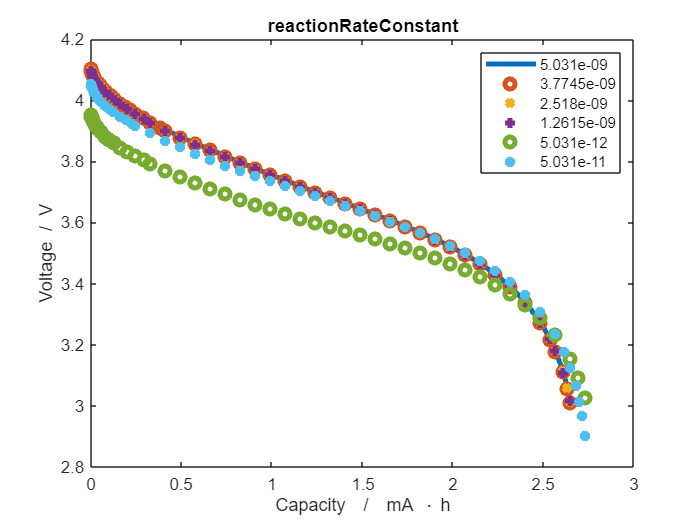

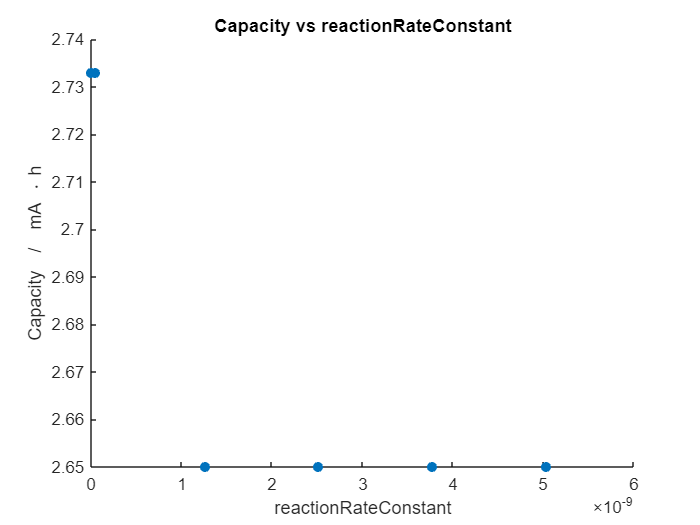

electrode_k="NegativeElectrode.";
crate_k=3;
kinetic_parameter_3=strcat(electrode_k,"Coating.ActiveMaterial.Interface.reactionRateConstant");
kinetic_parameter_3_vals=[linspace(5.031e-9,5.031e-12,5),5.031e-11];
plot_capacities(kinetic_parameter_3_vals,kinetic_parameter_3,crate_k)

#### **Example 6. **Transference number $$t_+$$ in the electrolyte

crate_t=3;
kinetic_parameter_5="Electrolyte.species.transferenceNumber";
kinetic_parameter_5_vals=[linspace(0.3,0.4,5),0.25];
plot_capacities(kinetic_parameter_5_vals,kinetic_parameter_5,crate_t)

### 4. Transport parameters

#### **Example 7. **Active particle radius- Solid diffusion

electrode_rad="NegativeElectrode.";
crate_radius=3;
transport_parameter_1=strcat(electrode_rad,"Coating.ActiveMaterial.SolidDiffusion.particleRadius");
transport_parameter_1_vals=[linspace(1,10,5)].*micro;
plot_capacities(transport_parameter_1_vals,transport_parameter_1,crate_radius)


#### **Example 8. **Bruggeman Coefficient in the electrodes- effective electronic conductivity

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

*** Simulation complete. Solved 45 control steps in 2 Seconds, 627 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 675 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 641 Milliseconds ***


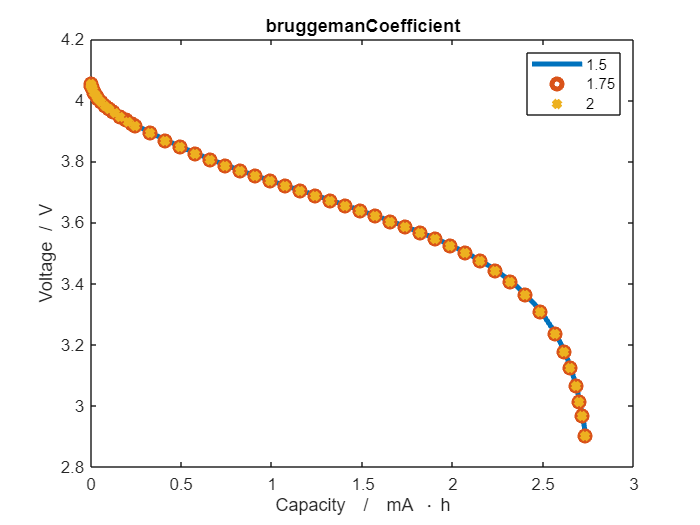

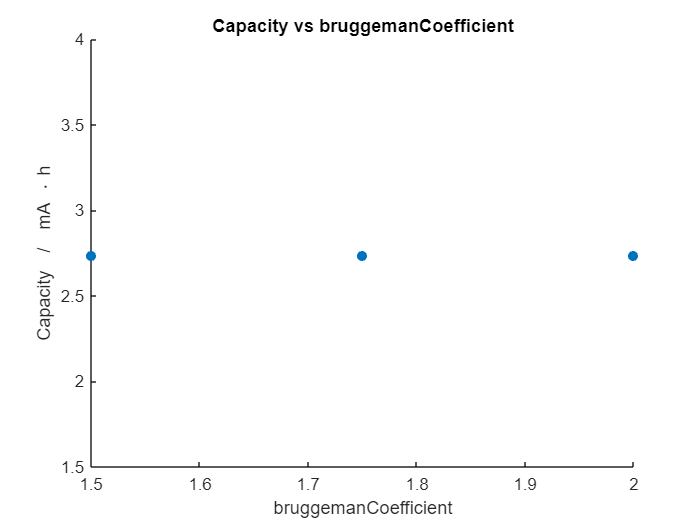

electrode_brug="NegativeElectrode.";
electrode_crate_brug=3;
transport_parameter_4=strcat(electrode_brug,"Coating.bruggemanCoefficient");% does not seem to affect the discharge profile
transport_parameter_4_vals=[linspace(1.0,2,3)];
plot_capacities(transport_parameter_4_vals,transport_parameter_4,electrode_crate_brug)

#### Example 9. Bruggeman Coefficient in the electrolyte-effective diffusion coefficient and ionic conductivity of electrolyte in the electrode region

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

*** Simulation complete. Solved 45 control steps in 2 Seconds, 812 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 4 Seconds, 423 Milliseconds ***


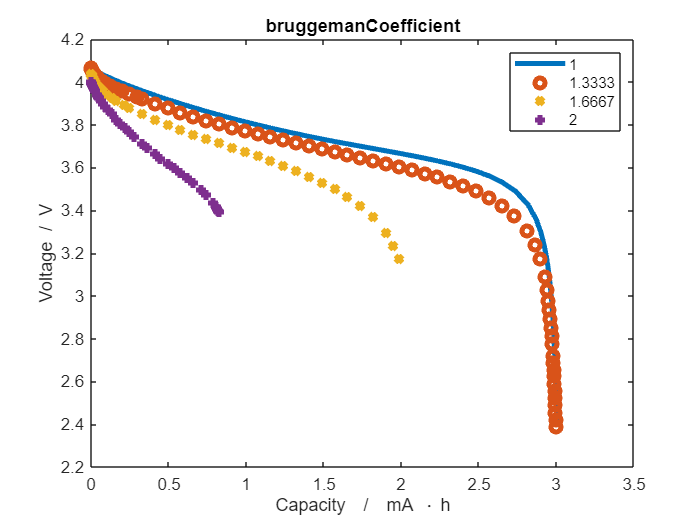

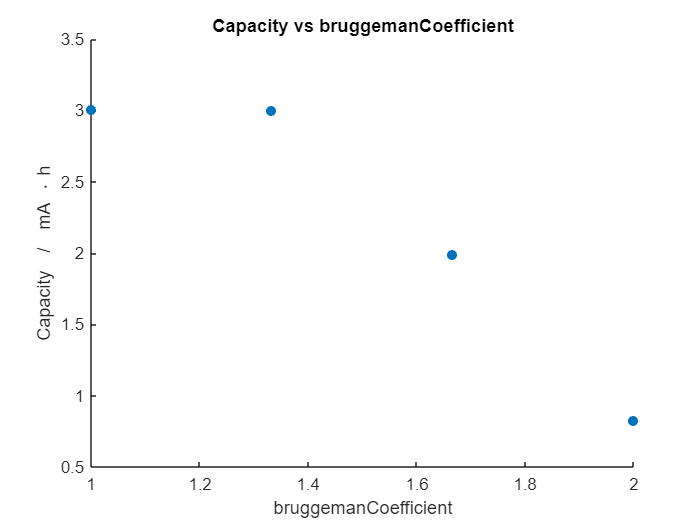

elyte_crate_brug=3;
transport_parameter_5="Electrolyte.bruggemanCoefficient"; % does not seem to affect the discharge profile
transport_parameter_5_vals=[linspace(1.0,2,4)];
plot_capacities(transport_parameter_5_vals,transport_parameter_5,elyte_crate_brug)

#### **Example 10. **Electronic conductivity of the active material in the electrodes

electrode_el_conductivity="NegativeElectrode.";
crate_el_conductivity=3;
transport_parameter_2=strcat(electrode_el_conductivity,"Coating.ActiveMaterial.electronicConductivity");%does not seem to affect the discharge profile
transport_parameter_2_vals=[linspace(100,1000,10)];
plot_capacities(transport_parameter_2_vals,transport_parameter_2,crate_el_conductivity)

#### **Example 11. **Electrolyte concentration-Diffusion Coefficient 

elyte_conc=3;
transport_parameter_3_vals=[linspace(0.5,1.5,5)];
transport_parameter_3="Electrolyte.initialConcentration.value";
plot_capacities(transport_parameter_3_vals,transport_parameter_3,elyte_conc)

**References**

[1][ L. Xia, E. Najafi, Z. Li, H.J. Bergveld, M.C.F. Donkers, "A computationally efficient implementation of a full and reduced-order electrochemistry-based model for Li-ion batteries," *Applied Energy*, vol. 208, pp. 1285-1296, 2017, ISSN 0306-2619](https://www.sciencedirect.com/science/article/pii/S0306261917313090.), [](https://doi.org/10.1016/j.apenergy.2017.09.025.)

[2] [Bharatkumar Suthar, Paul W. C. Northrop, Derek Rife, and Venkat R. Subramanian, "Effect of Porosity, Thickness and Tortuosity on Capacity Fade of Anode," *Journal of The Electrochemical Society*, vol. 162, no. 9, p. A1708, 2015. DOI: 10.1149/2.0061509jes. ](https://iopscience.iop.org/article/10.1149/2.0061509jes)

[3] [Venkat Srinivasan and John Newman, "Discharge Model for the Lithium Iron-Phosphate Electrode," *Journal of The Electrochemical Society*, vol. 151, no. 10, p. A1517, 2004. DOI: 10.1149/1.1785012](https://iopscience.iop.org/article/10.1149/1.1785012/meta).

function plot_capacities(parameterArray1,input_parameter1,CRate)
    % Function to take in the specific input parameter along with its
    % values and c-rate and plot the capacities
    %
    % Parameters:
    % parameterArray - a numeric vector
    % input_parameter - a string specifying the operation ('sum', 'mean', 'scale')
    % crate - a numeric value used for scaling (only for 'scale' operation)
    %
    % Returns:
    % None
    % instantiate an empty figure
    capacity_array = [];
    output = cell(size(parameterArray1));
    figure()
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json'); % load default input
    if nargin == 3
        jsonstruct.Control.CRate = CRate;        
     end
    output = cell(size(parameterArray1));
    markers={'-',"o",'x','+','o','*','x','v','d','^','s','>','<'};
    for i = 1:numel(parameterArray1)
        c = split(input_parameter1,'.');
        jsonstruct = setfield(jsonstruct,c{:},parameterArray1(i));  
        jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.1;
        % run the simulation and store the results in the output cell array
        output{i} = runBatteryJson(jsonstruct);
         % retrieve the states from the simulation result
        states = output{i}.states;
        % extract the time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % calculate the capacity
        capacity = time .* current;
        final_capacity=capacity(find(capacity, 1, 'last'))/(hour*milli);
        capacity_array(i)=final_capacity;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
        xlabel('Capacity  /  mA \cdot h')
        ylabel('Voltage  /  V')
        hold on
        L{i} = strcat(num2str(parameterArray1(i)));
        legend(L);
        title(c{end})
    end
    figure;
    scatter(parameterArray1,capacity_array,"filled")
    ylabel('Capacity  /  mA \cdot h')
    xlabel(c{end})
    title(strcat("Capacity vs ",c{end}));
end


